# Furuta Pendulum: Analytical Modelling & State-Space Representation

This Live Script derives the full 3D nonlinear equations of motion and linearized state-space representation of the Furuta Rotary Inverted Pendulum from first principles (Euler-Lagrange method).

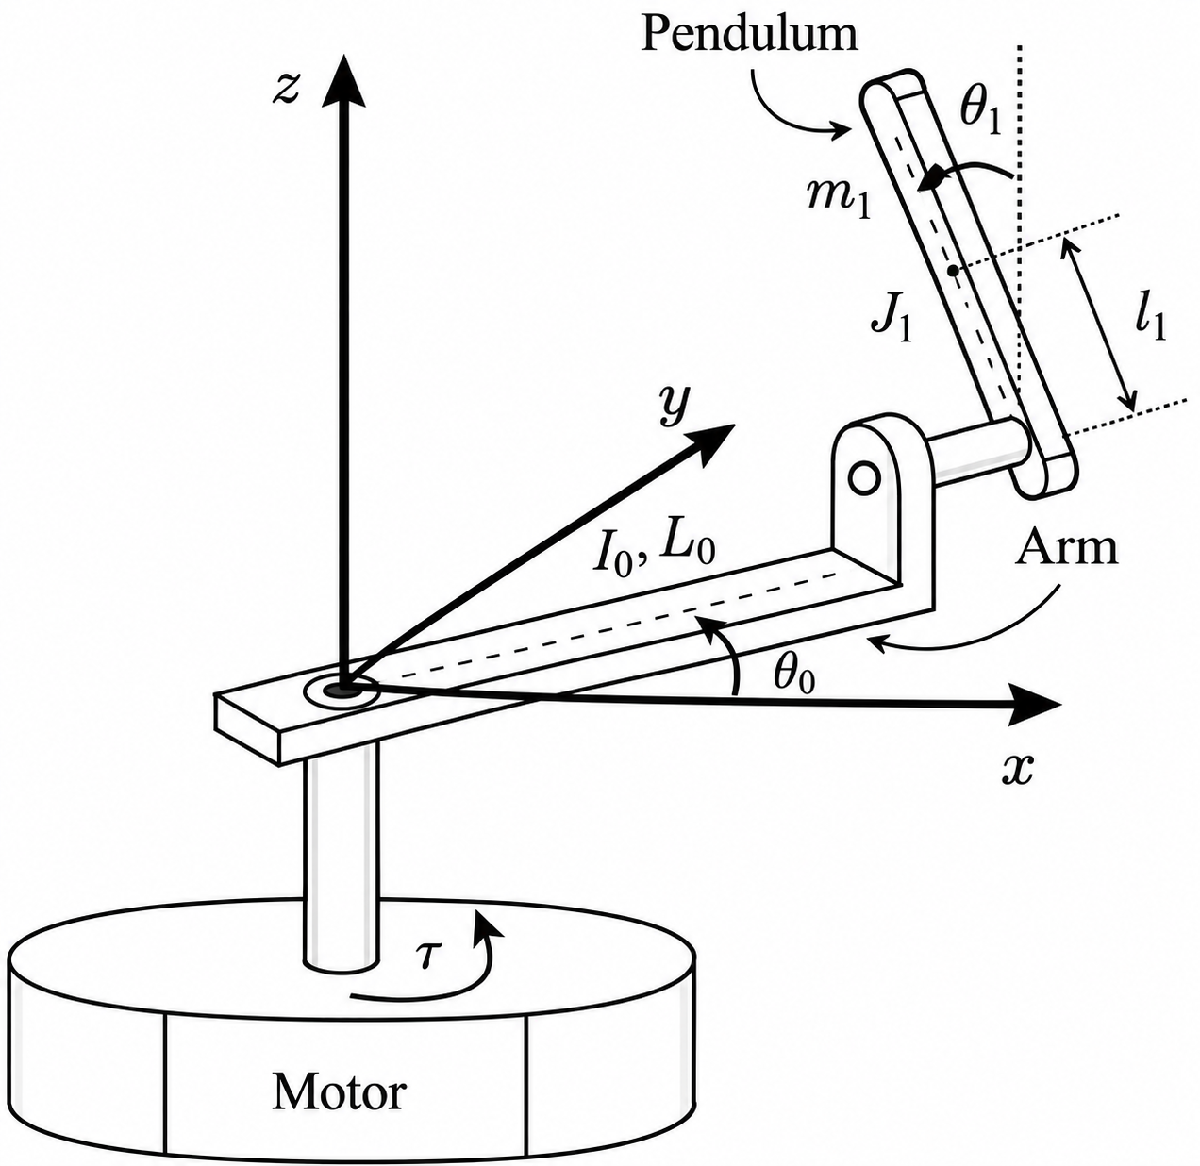

**Modeling Assumptions:**

- **Rigid links & ideal joints:** Both the horizontal rotary arm and the pendulum rod are rigid bodies (zero structural flex/torsion) connected by ideal revolute joints (zero bearing play or gearbox backlash).

- **Axisymmetric slender pendulum:** Transverse COM moments of inertia are equal ($J_1$), and axial spin inertia about the rod centerline is negligible ($J_{1,\parallel}
 \approx 0$).

- **Viscous joint dissipation:** Pivot friction is modeled as linear viscous damping ($b_0\dot{\theta}_0,\; b_1\dot{\theta}_1$); dry Coulomb friction and stiction are neglected.

- **DC motor dynamics:** Brushed DC motor with negligible electrical inductance ($L_a \approx 0$), rigid gearbox ratio $N$, and motor-shaft rotor inertia $J_m$.

## 1. Generalized Coordinates, Kinematics & Lagrangian

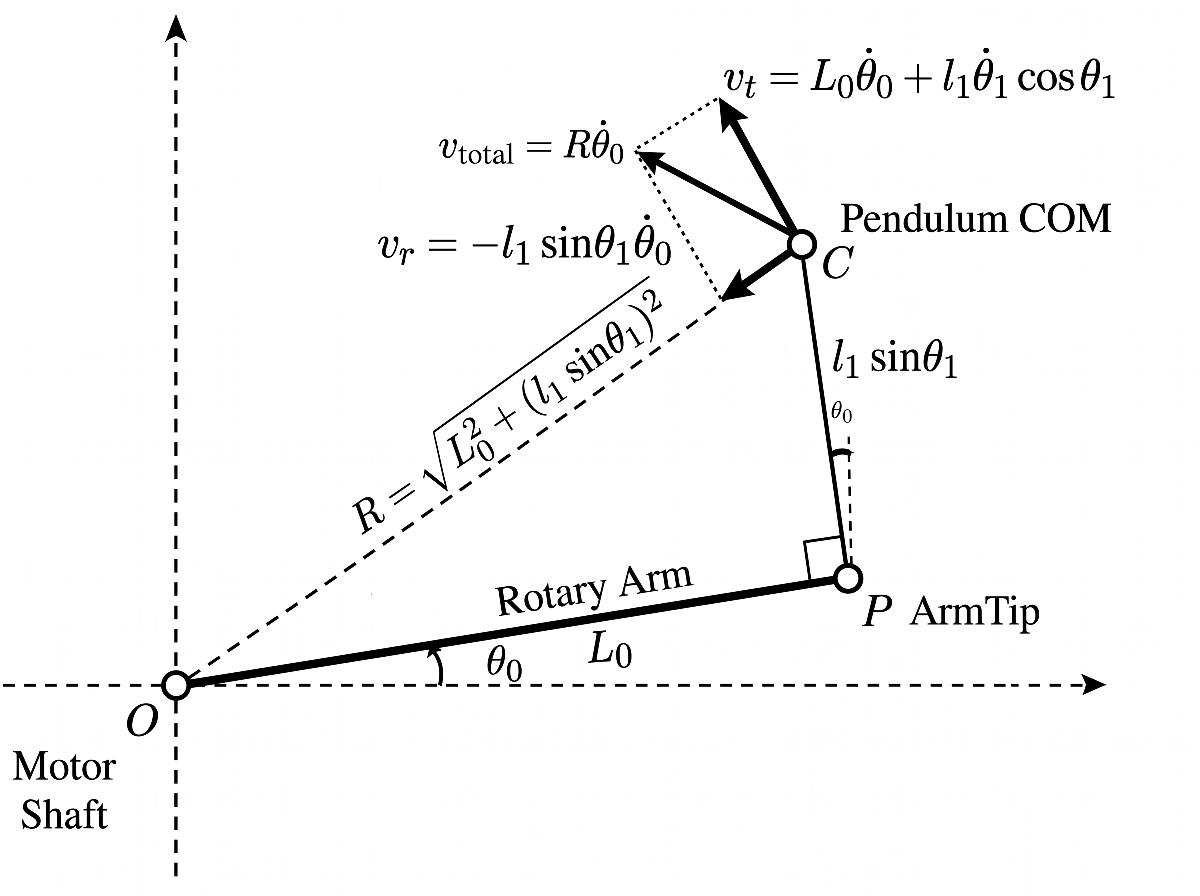

syms I0 L0 m1 l1 J1 g tau real
syms I0_hat J1_hat c_eq real
syms t theta0(t) theta1(t)

dtheta0 = diff(theta0, t);
dtheta1 = diff(theta1, t);

**Kinematics of the Pendulum Center of Mass (COM):** Reading the 3D position directly from the top-view geometry, the arm tip $P$ sits at $(L_0\cos\theta_0,\; L_0\sin\theta_0,\; 0)$, and the pendulum COM $C$ is offset perpendicular to the arm by length $l_1\sin\theta_1$ (tilted by $\theta_0$ from the vertical axis in the $XY$ plane) at height $l_1\cos\theta_1$:

X_com = L0*cos(theta0) - l1*sin(theta1)*sin(theta0);
Y_com = L0*sin(theta0) + l1*sin(theta1)*cos(theta0);
Z_com = l1*cos(theta1);

showEq("X_COM", X_com);

$$X_{\mathrm{COM}}=L_{0}\,\cos\left(\theta_{0}\right)-l_{1}\,\sin\left(\theta_{0}\right)\,\sin\left(\theta_{1}\right)$$

showEq("Y_COM", Y_com);

$$Y_{\mathrm{COM}}=L_{0}\,\sin\left(\theta_{0}\right)+l_{1}\,\cos\left(\theta_{0}\right)\,\sin\left(\theta_{1}\right)$$

showEq("Z_COM", Z_com);

$$Z_{\mathrm{COM}}=l_{1}\,\cos\left(\theta_{1}\right)$$

Differentiating $(X_{\text{COM}}, Y_{\text{COM}}, Z_{\text{COM}})$ with respect to time $t$ gives the inertial velocity components $(v_x, v_y, v_z)$, and $\sin^2\theta_0 + \cos^2\theta_0 = 1$ collapses $v_x^2 + v_y^2 + v_z^2$ cleanly:

vx   = diff(X_com, t);
showEq("v_x", vx);

$$v_{x}=-L_{0}\,{\dot{\theta }}_{0}\,\sin\left(\theta_{0}\right)-l_{1}\,\cos\left(\theta_{0}\right)\,\sin\left(\theta_{1}\right)\,{\dot{\theta }}_{0}-l_{1}\,\cos\left(\theta_{1}\right)\,\sin\left(\theta_{0}\right)\,{\dot{\theta }}_{1}$$

vy   = diff(Y_com, t);
showEq("v_y", vy);

$$v_{y}=L_{0}\,\cos\left(\theta_{0}\right)\,{\dot{\theta }}_{0}-l_{1}\,\sin\left(\theta_{0}\right)\,\sin\left(\theta_{1}\right)\,{\dot{\theta }}_{0}+l_{1}\,\cos\left(\theta_{0}\right)\,\cos\left(\theta_{1}\right)\,{\dot{\theta }}_{1}$$

vz   = diff(Z_com, t);
showEq("v_z", vz);

$$v_{z}=-l_{1}\,\sin\left(\theta_{1}\right)\,{\dot{\theta }}_{1}$$

v_sq = simplify(vx^2 + vy^2 + vz^2);
v_sq = simplify(subs(v_sq, cos(theta1)^2, 1 - sin(theta1)^2));
showEq("v^2", v_sq);

$$v^{2}={L_{0}}^{2}\,{{\dot{\theta }}_{0}}^{2}+{l_{1}}^{2}\,{{\dot{\theta }}_{0}}^{2}+{l_{1}}^{2}\,{{\dot{\theta }}_{1}}^{2}-{l_{1}}^{2}\,{\cos\left(\theta_{1}\right)}^{2}\,{{\dot{\theta }}_{0}}^{2}+2\,L_{0}\,l_{1}\,\cos\left(\theta_{1}\right)\,{\dot{\theta }}_{0}\,{\dot{\theta }}_{1}$$

**Kinetic and Potential Energies:** The total kinetic energy $T$ sums the rotary arm rotation ($T_0 = \frac{1}{2} I_0 \dot{\theta}_0^2$) and the pendulum link's 3D rotation plus COM translation ($T_1 = \frac{1}{2} J_1 (\dot{\theta}_1^2 + \sin^2\theta_1\,\dot{\theta}_0^2) + \frac{1}{2} m_1 (v_x^2 + v_y^2 + v_z^2)$):

T0 = sym(1)/2 * I0 * dtheta0^2;
T1 = sym(1)/2 * J1 * (dtheta1^2 + sin(theta1)^2 * dtheta0^2) + sym(1)/2 * m1 * v_sq;
T  = simplify(T0 + T1);
showEq("T", T);

$$T=\frac{1}{2}\,I_{0}\,{{\dot{\theta }}_{0}}^{2}+\frac{1}{2}\,J_{1}\,{{\dot{\theta }}_{1}}^{2}+\frac{1}{2}\,m_{1}\,{L_{0}}^{2}\,{{\dot{\theta }}_{0}}^{2}+\frac{1}{2}\,m_{1}\,{l_{1}}^{2}\,{{\dot{\theta }}_{0}}^{2}+\frac{1}{2}\,m_{1}\,{l_{1}}^{2}\,{{\dot{\theta }}_{1}}^{2}+\frac{1}{2}\,J_{1}\,{\sin\left(\theta_{1}\right)}^{2}\,{{\dot{\theta }}_{0}}^{2}-\frac{1}{2}\,m_{1}\,{l_{1}}^{2}\,{\cos\left(\theta_{1}\right)}^{2}\,{{\dot{\theta }}_{0}}^{2}+m_{1}\,L_{0}\,l_{1}\,\cos\left(\theta_{1}\right)\,{\dot{\theta }}_{0}\,{\dot{\theta }}_{1}$$

Because the rotary arm moves purely in the horizontal plane, only the pendulum contributes to gravitational potential energy $V$ (measured relative to the pivot height):

V = m1 * g * l1 * cos(theta1);
showEq("V", V);

$$V=m_{1}\,g\,l_{1}\,\cos\left(\theta_{1}\right)$$

Forming the Lagrangian $L = T - V$ combines the kinetic and potential energy landscapes into a single scalar function from which both equations of motion follow:

L = simplify(T - V);
showEq("L", L);

$$L=\frac{1}{2}\,I_{0}\,{{\dot{\theta }}_{0}}^{2}+\frac{1}{2}\,J_{1}\,{{\dot{\theta }}_{1}}^{2}+\frac{1}{2}\,m_{1}\,{L_{0}}^{2}\,{{\dot{\theta }}_{0}}^{2}+\frac{1}{2}\,m_{1}\,{l_{1}}^{2}\,{{\dot{\theta }}_{0}}^{2}+\frac{1}{2}\,m_{1}\,{l_{1}}^{2}\,{{\dot{\theta }}_{1}}^{2}+\frac{1}{2}\,J_{1}\,{\sin\left(\theta_{1}\right)}^{2}\,{{\dot{\theta }}_{0}}^{2}-m_{1}\,g\,l_{1}\,\cos\left(\theta_{1}\right)-\frac{1}{2}\,m_{1}\,{l_{1}}^{2}\,{\cos\left(\theta_{1}\right)}^{2}\,{{\dot{\theta }}_{0}}^{2}+m_{1}\,L_{0}\,l_{1}\,\cos\left(\theta_{1}\right)\,{\dot{\theta }}_{0}\,{\dot{\theta }}_{1}$$

## 2. Euler-Lagrange Equations of Motion

The Euler-Lagrange equation for each generalized coordinate $q_i \in \{\theta_0, \theta_1\}$ is:


$$\frac{d}{dt}\left(\frac{\partial L}{\partial \dot{q}_i}\right) - \frac{\partial
 L}{\partial q_i} = Q_i$$


where $Q_0 = \tau$ (applied motor torque) and $Q_1 = 0$ (unactuated pendulum).

**Coordinate 1 — Rotary Arm** ($\theta_0$): We first compute the generalized momentum $\frac{\partial L}{\partial \dot{\theta}_0}$ and its total time derivative $\frac{d}{dt}\left(\frac{\partial L}{\partial \dot{\theta}_0}\right)$:

dL_ddth0 = pDiff(L, dtheta0);
showEq("diff(L, theta_dot_0)", dL_ddth0);

$$\frac{\partial }{\partial {\dot{\theta }}_{0}}L=I_{0}\,{\dot{\theta }}_{0}+m_{1}\,{l_{1}}^{2}\,{\dot{\theta }}_{0}+J_{1}\,{\sin\left(\theta_{1}\right)}^{2}\,{\dot{\theta }}_{0}+m_{1}\,{L_{0}}^{2}\,{\dot{\theta }}_{0}-m_{1}\,{l_{1}}^{2}\,{\cos\left(\theta_{1}\right)}^{2}\,{\dot{\theta }}_{0}+m_{1}\,L_{0}\,l_{1}\,\cos\left(\theta_{1}\right)\,{\dot{\theta }}_{1}$$


ddt_p0   = diff(dL_ddth0, t);
showEq("diff(diff(L, theta_dot_0), t)", ddt_p0);

$$\frac{\partial }{\partial t}\frac{\partial }{\partial {\dot{\theta }}_{0}}L=I_{0}\,{\ddot{\theta }}_{0}+m_{1}\,{l_{1}}^{2}\,{\ddot{\theta }}_{0}+J_{1}\,{\sin\left(\theta_{1}\right)}^{2}\,{\ddot{\theta }}_{0}+m_{1}\,{L_{0}}^{2}\,{\ddot{\theta }}_{0}-m_{1}\,{l_{1}}^{2}\,{\cos\left(\theta_{1}\right)}^{2}\,{\ddot{\theta }}_{0}-m_{1}\,L_{0}\,l_{1}\,\sin\left(\theta_{1}\right)\,{{\dot{\theta }}_{1}}^{2}+2\,J_{1}\,\cos\left(\theta_{1}\right)\,\sin\left(\theta_{1}\right)\,{\dot{\theta }}_{0}\,{\dot{\theta }}_{1}+m_{1}\,L_{0}\,l_{1}\,\cos\left(\theta_{1}\right)\,{\ddot{\theta }}_{1}+2\,m_{1}\,{l_{1}}^{2}\,\cos\left(\theta_{1}\right)\,\sin\left(\theta_{1}\right)\,{\dot{\theta }}_{0}\,{\dot{\theta }}_{1}$$

Because $\theta_0$ does not appear explicitly in $L$, it is a cyclic coordinate ($\frac{\partial L}{\partial \theta_0} = 0$).

dL_dth0  = pDiff(L, theta0);
showEq("diff(L, theta_0)", dL_dth0);

$$\frac{\partial }{\partial \theta_{0}}L=0$$

Equating the Euler-Lagrange LHS to the applied motor torque $Q_0 = \tau$ gives the rotary arm equation of motion:

EL0      = simplify(ddt_p0 - dL_dth0);
showEq(EL0, tau);

$$I_{0}\,{\ddot{\theta }}_{0}+m_{1}\,{l_{1}}^{2}\,{\ddot{\theta }}_{0}+J_{1}\,{\sin\left(\theta_{1}\right)}^{2}\,{\ddot{\theta }}_{0}+m_{1}\,{L_{0}}^{2}\,{\ddot{\theta }}_{0}-m_{1}\,{l_{1}}^{2}\,{\cos\left(\theta_{1}\right)}^{2}\,{\ddot{\theta }}_{0}+J_{1}\,{\dot{\theta }}_{0}\,{\dot{\theta }}_{1}\,\sin\left(2\,\theta_{1}\right)-m_{1}\,L_{0}\,l_{1}\,\sin\left(\theta_{1}\right)\,{{\dot{\theta }}_{1}}^{2}+{l_{1}}^{2}\,m_{1}\,{\dot{\theta }}_{0}\,{\dot{\theta }}_{1}\,\sin\left(2\,\theta_{1}\right)+m_{1}\,L_{0}\,l_{1}\,\cos\left(\theta_{1}\right)\,{\ddot{\theta }}_{1}=\tau$$

**Coordinate 2 — Pendulum Link** ($\theta_1$): Repeating the procedure for $\theta_1$, we compute the pendulum generalized momentum $\frac{\partial L}{\partial \dot{\theta}_1}$, its time derivative, and the coordinate derivative $\frac{\partial L}{\partial \theta_1}$:

dL_ddth1 = pDiff(L, dtheta1);
showEq("diff(L, theta_dot_1)", dL_ddth1);

$$\frac{\partial }{\partial {\dot{\theta }}_{1}}L=J_{1}\,{\dot{\theta }}_{1}+m_{1}\,{l_{1}}^{2}\,{\dot{\theta }}_{1}+m_{1}\,L_{0}\,l_{1}\,\cos\left(\theta_{1}\right)\,{\dot{\theta }}_{0}$$


ddt_p1   = diff(dL_ddth1, t);
showEq("diff(diff(L, theta_dot_1), t)", ddt_p1);

$$\frac{\partial }{\partial t}\frac{\partial }{\partial {\dot{\theta }}_{1}}L=J_{1}\,{\ddot{\theta }}_{1}+m_{1}\,{l_{1}}^{2}\,{\ddot{\theta }}_{1}+m_{1}\,L_{0}\,l_{1}\,\cos\left(\theta_{1}\right)\,{\ddot{\theta }}_{0}-m_{1}\,L_{0}\,l_{1}\,\sin\left(\theta_{1}\right)\,{\dot{\theta }}_{0}\,{\dot{\theta }}_{1}$$


dL_dth1  = pDiff(L, theta1);
showEq("diff(L, theta_1)", dL_dth1);

$$\frac{\partial }{\partial \theta_{1}}L=J_{1}\,\cos\left(\theta_{1}\right)\,\sin\left(\theta_{1}\right)\,{{\dot{\theta }}_{0}}^{2}+m_{1}\,g\,l_{1}\,\sin\left(\theta_{1}\right)+m_{1}\,{l_{1}}^{2}\,\cos\left(\theta_{1}\right)\,\sin\left(\theta_{1}\right)\,{{\dot{\theta }}_{0}}^{2}-m_{1}\,L_{0}\,l_{1}\,\sin\left(\theta_{1}\right)\,{\dot{\theta }}_{0}\,{\dot{\theta }}_{1}$$

Subtracting $\frac{\partial L}{\partial \theta_1}$ from the time derivative cancels the $-m_1 L_0 l_1 \sin(\theta_1)\dot{\theta}_0\dot{\theta}_1$ cross-coupling term identically, while the 3D radial sweep introduces the Coriolis torque $(J_1 + m_1 l_1^2)\sin(2\theta_1)\dot{\theta}_0\dot{\theta}_1$ in Equation 1 and the centrifugal flinging torque $-\frac{1}{2}(J_1 + m_1 l_1^2)\sin(2\theta_1)\dot{\theta}_0^2$ in Equation 2:

EL1      = simplify(ddt_p1 - dL_dth1);
showEq(EL1, sym(0));

$$J_{1}\,{\ddot{\theta }}_{1}+m_{1}\,{l_{1}}^{2}\,{\ddot{\theta }}_{1}-\frac{1}{2}\,J_{1}\,{{\dot{\theta }}_{0}}^{2}\,\sin\left(2\,\theta_{1}\right)-m_{1}\,g\,l_{1}\,\sin\left(\theta_{1}\right)-\frac{1}{2}\,{l_{1}}^{2}\,m_{1}\,{{\dot{\theta }}_{0}}^{2}\,\sin\left(2\,\theta_{1}\right)+m_{1}\,L_{0}\,l_{1}\,\cos\left(\theta_{1}\right)\,{\ddot{\theta }}_{0}=0$$

## 3. Manipulator Equation Form: $M(\mathbf{q})\ddot{\mathbf{q}} + C(\mathbf{q}, \dot{\mathbf{q}})\dot{\mathbf{q}} + \mathbf{g}(\mathbf{q}) = \mathbf{\tau} - \mathbf{f}_{\text{fric}}$

Grouping the nonlinear Euler-Lagrange equations into standard robotic manipulator form (this generalization will be used in the **swing-up controller**):


$$M(\mathbf{q})\ddot{\mathbf{q}} + C(\mathbf{q}, \dot{\mathbf{q}})\dot{\mathbf{q}}
 + \mathbf{g}(\mathbf{q}) = \mathbf{\tau} - \mathbf{f}_{\text{fric}}$$


Collecting the coefficients of $\ddot{\mathbf{q}} = [\ddot{\theta}_0, \ddot{\theta}_1]^T$ gives the symmetric, configuration-dependent inertia matrix $M(\mathbf{q})$:

syms ddq0 ddq1 real
ddth_t = [diff(theta0, t, 2), diff(theta1, t, 2)];

% Extract nonlinear mass matrix M(q) and remaining velocity/gravity terms
EL_nl_a = subs(formula([EL0 == 0; EL1 == 0]), ddth_t, [ddq0, ddq1]);
[M_nl, rem_nl] = equationsToMatrix(EL_nl_a, [ddq0, ddq1]);
showEq("M_q", M_nl);

$$M_{q}=\left(\begin{array}{cc} I_{0}+m_{1}\,{L_{0}}^{2}+m_{1}\,{l_{1}}^{2}+J_{1}\,{\sin\left(\theta_{1}\right)}^{2}-m_{1}\,{l_{1}}^{2}\,{\cos\left(\theta_{1}\right)}^{2} & m_{1}\,L_{0}\,l_{1}\,\cos\left(\theta_{1}\right)\\ m_{1}\,L_{0}\,l_{1}\,\cos\left(\theta_{1}\right) & J_{1}+m_{1}\,{l_{1}}^{2} \end{array}\right)$$

Separating the remaining left-hand terms into velocity-independent gravitational torques $\mathbf{g}(\mathbf{q})$ and velocity-quadratic centrifugal/Coriolis torques $C(\mathbf{q}, \dot{\mathbf{q}})\dot{\mathbf{q}}$:

rem_nl = -rem_nl;  % Move remaining terms to LHS: M(q)*ddq + rem_nl = Q
g_vec = simplify(subs(rem_nl, [dtheta0, dtheta1], [0, 0]));
showEq("g_q", g_vec);

$$g_{q}=\left(\begin{array}{c} 0\\ -m_{1}\,g\,l_{1}\,\sin\left(\theta_{1}\right) \end{array}\right)$$


Cqdot = simplify(rem_nl - g_vec);
q_cells  = {theta0, theta1};
dq_cells = {dtheta0, dtheta1};
dq_vec   = [dtheta0; dtheta1];
C_nl     = sym(zeros(2, 2));
for i = 1:2
    for j = 1:2
        cij = sym(0);
        for k = 1:2
            cij = cij + sym(1)/2 * formula(pDiff(M_nl(i, j), q_cells{k}) ...
                + pDiff(M_nl(i, k), q_cells{j}) - pDiff(M_nl(j, k), q_cells{i})) * formula(dq_cells{k});
        end
        C_nl(i, j) = simplify(cij);
    end
end
assert(isequal(formula(simplify(C_nl * dq_vec - Cqdot)), sym([0; 0])), ...
    'Christoffel C(q, dq)*dq mismatch.');
showEq("C_q", C_nl);

$$C_{q}=\left(\begin{array}{cc} {\dot{\theta }}_{1}\,\sin\left(2\,\theta_{1}\right)\,\left(\frac{J_{1}}{2}+\frac{1}{2}\,{l_{1}}^{2}\,m_{1}\right) & {\dot{\theta }}_{0}\,\sin\left(2\,\theta_{1}\right)\,\left(\frac{J_{1}}{2}+\frac{1}{2}\,{l_{1}}^{2}\,m_{1}\right)-m_{1}\,L_{0}\,l_{1}\,\sin\left(\theta_{1}\right)\,{\dot{\theta }}_{1}\\ -{\dot{\theta }}_{0}\,\sin\left(2\,\theta_{1}\right)\,\left(\frac{J_{1}}{2}+\frac{1}{2}\,{l_{1}}^{2}\,m_{1}\right) & 0 \end{array}\right)$$

Finally, the generalized input torque vector $\mathbf{\tau}$ acts solely on the rotary arm (underactuated system), while viscous joint damping forms $\mathbf{f}_{\text{fric}}$:

tau_vec   = [tau; sym(0)];
showEq("tau_vec", tau_vec);

$$\vec{\tau }=\left(\begin{array}{c} \tau \\ 0 \end{array}\right)$$


syms b0 b1 real
f_fric    = [b0 * dtheta0; b1 * dtheta1];
showEq("f_fric", f_fric);

$$f_{\mathrm{fric}}=\left(\begin{array}{c} b_{0}\,{\dot{\theta }}_{0}\\ b_{1}\,{\dot{\theta }}_{1} \end{array}\right)$$

## 4. Small-Angle Linearization & State-Space Representation

Near either equilibrium ($\theta_1 \approx 0$ or $\pi$, with $\dot{\theta}_0 \approx 0,\; \dot{\theta}_1 \approx 0$), every 3D term ($\sin^2\theta_1$, $\sin(2\theta_1)\dot{\theta}_0\dot{\theta}_1$, and $\sin(2\theta_1)\dot{\theta}_0^2$) is second- or higher-order small and vanishes identically—collapsing the full 3D mechanics back into the classic linear equations. We follow a three-step sequence:

- Linearize about the **upright equilibrium** ($\theta_1 = 0$).

- Linearize about the **downward equilibrium** ($\theta_1 = \pi + \tilde{\theta}_1$).

- Spot the sign-flip pattern and unify both equilibria via $c_{\text{eq}}
 = \cos\theta_{1,\text{eq}} \in \{+1, -1\}$.

Throughout Section 4 (frictionless torque-driven baseline, $u = \tau$), we group the constant inertia terms as $\hat{I}_0 = I_0 + m_1 L_0^2$ and $\hat{J}_1 = J_1 + m_1 l_1^2$.

**4.1 Upright Equilibrium** ($\theta_1 = 0,\; \dot{\theta}_1 \approx 0$): Applying $\cos\theta_1 \approx 1$, $\sin\theta_1 \approx \theta_1$, and truncating higher-order perturbation products ($\theta_1^2, \dot{\theta}_0^2, \dot{\theta}_1^2, \theta_1\dot{\theta}_0, \ldots \to 0$) yields constant inertia $M_{\text{up}}$, vanishing $C_{\text{lin}} = \mathbf{0}$, and linear gravity $\mathbf{g}_{\text{up}}$:

M_up_lin     = linearizePerturb(M_nl,  I0_hat - m1*L0^2, J1_hat - m1*l1^2, sym(1), theta1, false);
Cqdot_up_lin = linearizePerturb(Cqdot, I0_hat - m1*L0^2, J1_hat - m1*l1^2, sym(1), theta1, true);
g_up_lin     = linearizePerturb(g_vec, I0_hat - m1*L0^2, J1_hat - m1*l1^2, sym(1), theta1, true);

showEq("M_up", M_up_lin);

$$M_{\mathrm{up}}=\left(\begin{array}{cc} {\hat{I}}_{0} & m_{1}\,L_{0}\,l_{1}\\ m_{1}\,L_{0}\,l_{1} & {\hat{J}}_{1} \end{array}\right)$$

showEq("C_q_qdot_lin", Cqdot_up_lin);

$$C_{\ddddot{q},\mathrm{lin}}=\left(\begin{array}{c} 0\\ 0 \end{array}\right)$$

showEq("g_up", g_up_lin);

$$g_{\mathrm{up}}=\left(\begin{array}{c} 0\\ -m_{1}\,g\,l_{1}\,\theta_{1} \end{array}\right)$$

Substituting these linearized components into the frictionless baseline yields the two coupled linear differential equations:

EL0_up_lin = linearizePerturb(EL0, I0_hat - m1*L0^2, J1_hat - m1*l1^2, sym(1), theta1, true);
EL1_up_lin = linearizePerturb(EL1, I0_hat - m1*L0^2, J1_hat - m1*l1^2, sym(1), theta1, true);

showEq(EL0_up_lin, tau);

$${\hat{I}}_{0}\,{\ddot{\theta }}_{0}+m_{1}\,L_{0}\,l_{1}\,{\ddot{\theta }}_{1}=\tau$$

showEq(EL1_up_lin, sym(0));

$${\hat{J}}_{1}\,{\ddot{\theta }}_{1}-m_{1}\,g\,l_{1}\,\theta_{1}+m_{1}\,L_{0}\,l_{1}\,{\ddot{\theta }}_{0}=0$$

Writing these coupled linear ODEs in matrix form $M_{\text{up}}\ddot{\mathbf{q}} = \mathbf{f}_{\text{up}}$ separates the acceleration coupling ($M_{\text{up}}$) from the restoring and input forces ($\mathbf{f}_{\text{up}}$):

syms ddq0 ddq1 real
ddth_t    = [diff(theta0, t, 2), diff(theta1, t, 2)];
EL_up_a   = subs(formula([EL0_up_lin == tau, EL1_up_lin == 0]), ddth_t, [ddq0, ddq1]);
[M_up, f_up] = equationsToMatrix(EL_up_a, [ddq0, ddq1]);
M_up = simplify(M_up);
f_up = simplify(f_up);

showEq("M_up", M_up);

$$M_{\mathrm{up}}=\left(\begin{array}{cc} {\hat{I}}_{0} & m_{1}\,L_{0}\,l_{1}\\ m_{1}\,L_{0}\,l_{1} & {\hat{J}}_{1} \end{array}\right)$$

showEq("f_up", f_up);

$$f_{\mathrm{up}}=\left(\begin{array}{c} \tau \\ m_{1}\,g\,l_{1}\,\theta_{1} \end{array}\right)$$

Computing the determinant $D_{\text{up}} = \det(M_{\text{up}})$ and inverting $M_{\text{up}}^{-1} = \frac{1}{D_{\text{up}}}\mathrm{adj}(M_{\text{up}})$ decouples the angular accelerations $\ddot{\theta}_0$ and $\ddot{\theta}_1$:

D_up     = simplify(det(M_up));
M_up_inv = simplify(inv(M_up));
ddq_up   = simplify(M_up \ f_up);

showEq("D_up", D_up);

$$D_{\mathrm{up}}={\hat{I}}_{0}\,{\hat{J}}_{1}-{m_{1}}^{2}\,{L_{0}}^{2}\,{l_{1}}^{2}$$

showEq("M_up_inv", M_up_inv);

$$\begin{array}{l} M_{\mathrm{up},\mathrm{inv}}=\left(\begin{array}{cc} \frac{{\hat{J}}_{1}}{\sigma_{1}} & \frac{-L_{0}\,l_{1}\,m_{1}}{\sigma_{1}}\\ \frac{-L_{0}\,l_{1}\,m_{1}}{\sigma_{1}} & \frac{{\hat{I}}_{0}}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\hat{I}}_{0}\,{\hat{J}}_{1}-{L_{0}}^{2}\,{l_{1}}^{2}\,{m_{1}}^{2} \end{array}$$

showEq("theta_ddot_0_up", ddq_up(1));

$${\ddot{\theta }}_{0,\mathrm{up}}=\frac{{\hat{J}}_{1}\,\tau -L_{0}\,g\,{l_{1}}^{2}\,{m_{1}}^{2}\,\theta_{1}}{{\hat{I}}_{0}\,{\hat{J}}_{1}-{L_{0}}^{2}\,{l_{1}}^{2}\,{m_{1}}^{2}}$$

showEq("theta_ddot_1_up", ddq_up(2));

$${\ddot{\theta }}_{1,\mathrm{up}}=\frac{-l_{1}\,m_{1}\,\left(L_{0}\,\tau -{\hat{I}}_{0}\,g\,\theta_{1}\right)}{{\hat{I}}_{0}\,{\hat{J}}_{1}-{L_{0}}^{2}\,{l_{1}}^{2}\,{m_{1}}^{2}}$$

Choosing the state vector $\mathbf{x} = [\theta_0,\; \dot{\theta}_0,\; \theta_1,\; \dot{\theta}_1]^T$, input $u = \tau$, and measured outputs $\mathbf{y} = [\theta_0,\; \theta_1]^T$, we take the Jacobians $A_{\text{up}} = \frac{\partial \dot{\mathbf{x}}}{\partial \mathbf{x}}$ and $B_{\text{up}} = \frac{\partial \dot{\mathbf{x}}}{\partial u}$:

syms x1 x2 x3 x4 real
x_alg       = [x1; x2; x3; x4];
xdot_up_t   = [dtheta0; ddq_up(1); dtheta1; ddq_up(2)];
xdot_up_alg = subs(formula(xdot_up_t), [dtheta0, dtheta1, theta0, theta1], [x2, x4, x1, x3]);

A_up = simplify(jacobian(xdot_up_alg, x_alg));
B_up = simplify(jacobian(xdot_up_alg, tau));
C    = sym([1 0 0 0; 0 0 1 0]);
D_ss = sym([0; 0]);

showEq("A_up", A_up);

$$A_{\mathrm{up}}=\left(\begin{array}{cccc} 0 & 1 & 0 & 0\\ 0 & 0 & \frac{-L_{0}\,g\,{l_{1}}^{2}\,{m_{1}}^{2}}{{\hat{I}}_{0}\,{\hat{J}}_{1}-{L_{0}}^{2}\,{l_{1}}^{2}\,{m_{1}}^{2}} & 0\\ 0 & 0 & 0 & 1\\ 0 & 0 & \frac{{\hat{I}}_{0}\,g\,l_{1}\,m_{1}}{{\hat{I}}_{0}\,{\hat{J}}_{1}-{L_{0}}^{2}\,{l_{1}}^{2}\,{m_{1}}^{2}} & 0 \end{array}\right)$$

showEq("B_up", B_up);

$$B_{\mathrm{up}}=\left(\begin{array}{c} 0\\ \frac{{\hat{J}}_{1}}{{\hat{I}}_{0}\,{\hat{J}}_{1}-{L_{0}}^{2}\,{l_{1}}^{2}\,{m_{1}}^{2}}\\ 0\\ \frac{-L_{0}\,l_{1}\,m_{1}}{{\hat{I}}_{0}\,{\hat{J}}_{1}-{L_{0}}^{2}\,{l_{1}}^{2}\,{m_{1}}^{2}} \end{array}\right)$$

showEq("C", C);

$$C=\left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 0 & 1 & 0 \end{array}\right)$$

showEq("D", D_ss);

$$\text{D}=\left(\begin{array}{c} 0\\ 0 \end{array}\right)$$

**4.2 Downward Equilibrium** ($\theta_1 = \pi + \tilde{\theta}_1,\; \dot{\tilde{\theta}}_1 \approx 0$): Around the hanging equilibrium, *both* trigonometric terms change sign: $\cos(\pi + \tilde{\theta}_1) \approx -1$ and $\sin(\pi + \tilde{\theta}_1) \approx -\tilde{\theta}_1$ (denoting $\tilde{\theta}_1$ by $\theta_1$ in local coordinates). Repeating the exact same steps gives:

[M_down, f_down, D_down, ddq_down, A_down, B_down] = deriveLinearSS( ...
    EL0, EL1, tau, sym(0), tau, ...
    I0_hat - m1*L0^2, J1_hat - m1*l1^2, sym(-1), -theta1);

showEq("M_down", M_down);

$$M_{\mathrm{down}}=\left(\begin{array}{cc} {\hat{I}}_{0} & -m_{1}\,L_{0}\,l_{1}\\ -m_{1}\,L_{0}\,l_{1} & {\hat{J}}_{1} \end{array}\right)$$

showEq("D_down", D_down);

$$D_{\mathrm{down}}={\hat{I}}_{0}\,{\hat{J}}_{1}-{m_{1}}^{2}\,{L_{0}}^{2}\,{l_{1}}^{2}$$

showEq("A_down", A_down);

$$A_{\mathrm{down}}=\left(\begin{array}{cccc} 0 & 1 & 0 & 0\\ 0 & 0 & \frac{-L_{0}\,g\,{l_{1}}^{2}\,{m_{1}}^{2}}{{\hat{I}}_{0}\,{\hat{J}}_{1}-{L_{0}}^{2}\,{l_{1}}^{2}\,{m_{1}}^{2}} & 0\\ 0 & 0 & 0 & 1\\ 0 & 0 & \frac{-{\hat{I}}_{0}\,g\,l_{1}\,m_{1}}{{\hat{I}}_{0}\,{\hat{J}}_{1}-{L_{0}}^{2}\,{l_{1}}^{2}\,{m_{1}}^{2}} & 0 \end{array}\right)$$

showEq("B_down", B_down);

$$B_{\mathrm{down}}=\left(\begin{array}{c} 0\\ \frac{{\hat{J}}_{1}}{{\hat{I}}_{0}\,{\hat{J}}_{1}-{L_{0}}^{2}\,{l_{1}}^{2}\,{m_{1}}^{2}}\\ 0\\ \frac{L_{0}\,l_{1}\,m_{1}}{{\hat{I}}_{0}\,{\hat{J}}_{1}-{L_{0}}^{2}\,{l_{1}}^{2}\,{m_{1}}^{2}} \end{array}\right)$$

**4.3 Pattern Recognition & Generalization** ($c_{\text{eq}} = \cos\theta_{1,\text{eq}} \in \{+1, -1\}$): Comparing $(A_{\text{up}}, B_{\text{up}})$ and $(A_{\text{down}}, B_{\text{down}})$ side by side reveals an exact algebraic pattern:

- $D = \hat{I}_0 \hat{J}_1 - (m_1 L_0 l_1)^2$ and $A_{23}$ are **invariant** because $(-1)^2 = +1$ (both $M_{12}^{-1}$ and gravity flip sign, so the two minus signs cancel).

- $A_{43}$ and $B_4$ **flip sign** because each depends linearly on $\cos\theta_{1,\text{eq}}$ or $\sin(\theta_{1,\text{eq}} + \tilde{\theta}_1)$.

Defining $c_{\text{eq}} = \cos\theta_{1,\text{eq}} \in \{+1, -1\}$ so $\cos\theta_1 \approx c_{\text{eq}}$ and $\sin\theta_1 \approx c_{\text{eq}}\,\tilde{\theta}_1$ (with $c_{\text{eq}}^2 = 1$), both equilibria collapse into one unified representation $(A(c_{\text{eq}}), B(c_{\text{eq}}))$:

[~, ~, D_gen, ~, A_gen, B_gen] = deriveLinearSS( ...
    EL0, EL1, tau, sym(0), tau, ...
    I0_hat - m1*L0^2, J1_hat - m1*l1^2, c_eq, c_eq * theta1);

D_gen = simplify(subs(D_gen, c_eq^2, 1));
A_gen = simplify(subs(A_gen, c_eq^2, 1));
B_gen = simplify(subs(B_gen, c_eq^2, 1));

showEq("D", D_gen);

$$\text{D}={\hat{I}}_{0}\,{\hat{J}}_{1}-{m_{1}}^{2}\,{L_{0}}^{2}\,{l_{1}}^{2}$$

showEq("A", A_gen);

$$A=\left(\begin{array}{cccc} 0 & 1 & 0 & 0\\ 0 & 0 & \frac{-L_{0}\,g\,{l_{1}}^{2}\,{m_{1}}^{2}}{{\hat{I}}_{0}\,{\hat{J}}_{1}-{L_{0}}^{2}\,{l_{1}}^{2}\,{m_{1}}^{2}} & 0\\ 0 & 0 & 0 & 1\\ 0 & 0 & \frac{{\hat{I}}_{0}\,c_{\mathrm{eq}}\,g\,l_{1}\,m_{1}}{{\hat{I}}_{0}\,{\hat{J}}_{1}-{L_{0}}^{2}\,{l_{1}}^{2}\,{m_{1}}^{2}} & 0 \end{array}\right)$$

showEq("B", B_gen);

$$B=\left(\begin{array}{c} 0\\ \frac{{\hat{J}}_{1}}{{\hat{I}}_{0}\,{\hat{J}}_{1}-{L_{0}}^{2}\,{l_{1}}^{2}\,{m_{1}}^{2}}\\ 0\\ \frac{-L_{0}\,c_{\mathrm{eq}}\,l_{1}\,m_{1}}{{\hat{I}}_{0}\,{\hat{J}}_{1}-{L_{0}}^{2}\,{l_{1}}^{2}\,{m_{1}}^{2}} \end{array}\right)$$

## 5. Full Electromechanical Model: Rotor Inertia, Friction, Gearbox & DC Motor

Extending the idealized torque-driven model to include the full physical actuator and joint dissipation:

- Motor rotor inertia $J_m$ referred to the motor shaft ($\omega_m = N\dot{\theta}_0$), adding rotor kinetic energy $T_m = \frac{1}{2} J_m (N\dot{\theta}_0)^2 = \frac{1}{2}(N^2
 J_m)\dot{\theta}_0^2$ to the arm equation of motion. Thus $\hat{I}_0$ updates from $I_0 + m_1 L_0^2$ to $\hat{I}_0 = I_0 + N^2 J_m + m_1 L_0^2$ (while $I_0$ remains purely the arm/hub inertia).

- Viscous damping at both pivots ($b_0, b_1$).

- Gearbox ratio $N$ ($\tau_{\text{arm}} = N\tau_m$) and DC motor armature voltage input $u = V_a$ with resistance $R_m$, torque constant $k_t$, and back-EMF constant  $k_b$ (neglecting fast electrical inductance $L_a \approx 0$):


$$\tau = \frac{N k_t}{R_m} V_a - \frac{N^2 k_t k_b}{R_m} \dot{\theta}_0$$


syms Jm b0 b1 N R_m k_t k_b V_a real

EL0_em    = EL0 + N^2 * Jm * diff(theta0, t, 2);
EL1_em    = EL1;
tau_motor = (N * k_t / R_m) * V_a - (N^2 * k_t * k_b / R_m) * dtheta0;
Q0_full   = tau_motor - b0 * dtheta0;
Q1_full   = -b1 * dtheta1;

showEq("tau", tau_motor);

$$\tau =\frac{N\,V_{a}\,k_{t}}{R_{m}}-\frac{N^{2}\,k_{b}\,k_{t}\,{\dot{\theta }}_{0}}{R_{m}}$$

showEq("Q_0", Q0_full);

$$Q_{0}=\frac{N\,V_{a}\,k_{t}}{R_{m}}-b_{0}\,{\dot{\theta }}_{0}-\frac{N^{2}\,k_{b}\,k_{t}\,{\dot{\theta }}_{0}}{R_{m}}$$

showEq("Q_1", Q1_full);

$$Q_{1}=-b_{1}\,{\dot{\theta }}_{1}$$

**5.1 Upright Electromechanical Matrices** ($\theta_1 = 0$): Substituting $\hat{I}_0 = I_0 + N^2 J_m + m_1 L_0^2$ and $\hat{J}_1 = J_1 + m_1 l_1^2$ around the upright apex:

[~, ~, ~, ddq_full_up, A_full_up, B_full_up] = deriveLinearSS( ...
    EL0_em, EL1_em, Q0_full, Q1_full, V_a, ...
    I0_hat - N^2*Jm - m1*L0^2, J1_hat - m1*l1^2, sym(1), theta1);

showEq("theta_ddot_0_up", ddq_full_up(1));

$${\ddot{\theta }}_{0,\mathrm{up}}=\frac{-\left({\hat{J}}_{1}\,R_{m}\,b_{0}\,{\dot{\theta }}_{0}-{\hat{J}}_{1}\,N\,V_{a}\,k_{t}+{\hat{J}}_{1}\,{\dot{\theta }}_{0}\,N^{2}\,k_{b}\,k_{t}+{m_{1}}^{2}\,g\,L_{0}\,{l_{1}}^{2}\,\theta_{1}\,R_{m}-L_{0}\,R_{m}\,b_{1}\,l_{1}\,m_{1}\,{\dot{\theta }}_{1}\right)}{R_{m}\,\left({\hat{I}}_{0}\,{\hat{J}}_{1}-{L_{0}}^{2}\,{l_{1}}^{2}\,{m_{1}}^{2}\right)}$$

showEq("theta_ddot_1_up", ddq_full_up(2));

$${\ddot{\theta }}_{1,\mathrm{up}}=\frac{L_{0}\,R_{m}\,b_{0}\,l_{1}\,m_{1}\,{\dot{\theta }}_{0}-m_{1}\,L_{0}\,l_{1}\,N\,V_{a}\,k_{t}-{\hat{I}}_{0}\,b_{1}\,{\dot{\theta }}_{1}\,R_{m}+m_{1}\,g\,{\hat{I}}_{0}\,l_{1}\,\theta_{1}\,R_{m}+L_{0}\,N^{2}\,k_{b}\,k_{t}\,l_{1}\,m_{1}\,{\dot{\theta }}_{0}}{R_{m}\,\left({\hat{I}}_{0}\,{\hat{J}}_{1}-{L_{0}}^{2}\,{l_{1}}^{2}\,{m_{1}}^{2}\right)}$$

showEq("A_full_up", A_full_up);

$$\begin{array}{l} A_{\mathrm{full},\mathrm{up}}=\left(\begin{array}{cccc} 0 & 1 & 0 & 0\\ 0 & \frac{-{\hat{J}}_{1}\,\sigma_{2}}{R_{m}\,\sigma_{1}} & \frac{-L_{0}\,g\,{l_{1}}^{2}\,{m_{1}}^{2}}{\sigma_{1}} & \frac{L_{0}\,b_{1}\,l_{1}\,m_{1}}{\sigma_{1}}\\ 0 & 0 & 0 & 1\\ 0 & \frac{L_{0}\,l_{1}\,m_{1}\,\sigma_{2}}{R_{m}\,\sigma_{1}} & \frac{{\hat{I}}_{0}\,g\,l_{1}\,m_{1}}{\sigma_{1}} & \frac{-{\hat{I}}_{0}\,b_{1}}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\hat{I}}_{0}\,{\hat{J}}_{1}-{L_{0}}^{2}\,{l_{1}}^{2}\,{m_{1}}^{2}\\ \sigma_{2}=k_{b}\,k_{t}\,N^{2}+R_{m}\,b_{0} \end{array}$$

showEq("B_full_up", B_full_up);

$$B_{\mathrm{full},\mathrm{up}}=\left(\begin{array}{c} 0\\ \frac{{\hat{J}}_{1}\,N\,k_{t}}{R_{m}\,\left({\hat{I}}_{0}\,{\hat{J}}_{1}-{L_{0}}^{2}\,{l_{1}}^{2}\,{m_{1}}^{2}\right)}\\ 0\\ \frac{-L_{0}\,N\,k_{t}\,l_{1}\,m_{1}}{R_{m}\,\left({\hat{I}}_{0}\,{\hat{J}}_{1}-{L_{0}}^{2}\,{l_{1}}^{2}\,{m_{1}}^{2}\right)} \end{array}\right)$$

**5.2 Downward Electromechanical Matrices** ($\theta_1 = \pi + \tilde{\theta}_1$): Repeating at the hanging equilibrium ($\cos\theta_1 \approx -1,\; \sin\theta_1 \approx -\tilde{\theta}_1$):

[~, ~, ~, ddq_full_down, A_full_down, B_full_down] = deriveLinearSS( ...
    EL0_em, EL1_em, Q0_full, Q1_full, V_a, ...
    I0_hat - N^2*Jm - m1*L0^2, J1_hat - m1*l1^2, sym(-1), -theta1);

showEq("A_full_down", A_full_down);

$$\begin{array}{l} A_{\mathrm{full},\mathrm{down}}=\left(\begin{array}{cccc} 0 & 1 & 0 & 0\\ 0 & \frac{-{\hat{J}}_{1}\,\sigma_{2}}{R_{m}\,\sigma_{1}} & \frac{-L_{0}\,g\,{l_{1}}^{2}\,{m_{1}}^{2}}{\sigma_{1}} & \frac{-L_{0}\,b_{1}\,l_{1}\,m_{1}}{\sigma_{1}}\\ 0 & 0 & 0 & 1\\ 0 & \frac{-L_{0}\,l_{1}\,m_{1}\,\sigma_{2}}{R_{m}\,\sigma_{1}} & \frac{-{\hat{I}}_{0}\,g\,l_{1}\,m_{1}}{\sigma_{1}} & \frac{-{\hat{I}}_{0}\,b_{1}}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\hat{I}}_{0}\,{\hat{J}}_{1}-{L_{0}}^{2}\,{l_{1}}^{2}\,{m_{1}}^{2}\\ \sigma_{2}=k_{b}\,k_{t}\,N^{2}+R_{m}\,b_{0} \end{array}$$

showEq("B_full_down", B_full_down);

$$B_{\mathrm{full},\mathrm{down}}=\left(\begin{array}{c} 0\\ \frac{{\hat{J}}_{1}\,N\,k_{t}}{R_{m}\,\left({\hat{I}}_{0}\,{\hat{J}}_{1}-{L_{0}}^{2}\,{l_{1}}^{2}\,{m_{1}}^{2}\right)}\\ 0\\ \frac{L_{0}\,N\,k_{t}\,l_{1}\,m_{1}}{R_{m}\,\left({\hat{I}}_{0}\,{\hat{J}}_{1}-{L_{0}}^{2}\,{l_{1}}^{2}\,{m_{1}}^{2}\right)} \end{array}\right)$$

**5.3 Unified Generalization & Code Export** ($c_{\text{eq}} \in \{+1, -1\}$): Notice that viscous damping and back-EMF introduce two additional cross-coupling entries ($A_{24}$ from $b_1$ and $A_{42}$ from $b_0 + \frac{N^2 k_t k_b}{R_m}$) that *also* flip sign with $c_{\text{eq}}$ because $M_{12} = c_{\text{eq}}\,m_1 L_0 l_1$, while $A_{23}$ remains invariant ($c_{\text{eq}}^2 = 1$). Forming the unified electromechanical matrices $(A_{\text{full}}(c_{\text{eq}}), B_{\text{full}}(c_{\text{eq}}))$:

[~, ~, ~, ~, A_full_gen, B_full_gen] = deriveLinearSS( ...
    EL0_em, EL1_em, Q0_full, Q1_full, V_a, ...
    I0_hat - N^2*Jm - m1*L0^2, J1_hat - m1*l1^2, c_eq, c_eq * theta1);

A_full_gen = simplify(subs(A_full_gen, c_eq^2, 1));
B_full_gen = simplify(subs(B_full_gen, c_eq^2, 1));
C_full     = C;
D_full     = D_ss;

showEq("A_full", A_full_gen);

$$\begin{array}{l} A_{\mathrm{full}}=\left(\begin{array}{cccc} 0 & 1 & 0 & 0\\ 0 & \frac{-{\hat{J}}_{1}\,\sigma_{2}}{R_{m}\,\sigma_{1}} & \frac{-L_{0}\,g\,{l_{1}}^{2}\,{m_{1}}^{2}}{\sigma_{1}} & \frac{L_{0}\,b_{1}\,c_{\mathrm{eq}}\,l_{1}\,m_{1}}{\sigma_{1}}\\ 0 & 0 & 0 & 1\\ 0 & \frac{L_{0}\,c_{\mathrm{eq}}\,l_{1}\,m_{1}\,\sigma_{2}}{R_{m}\,\sigma_{1}} & \frac{{\hat{I}}_{0}\,c_{\mathrm{eq}}\,g\,l_{1}\,m_{1}}{\sigma_{1}} & \frac{-{\hat{I}}_{0}\,b_{1}}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\hat{I}}_{0}\,{\hat{J}}_{1}-{L_{0}}^{2}\,{l_{1}}^{2}\,{m_{1}}^{2}\\ \sigma_{2}=k_{b}\,k_{t}\,N^{2}+R_{m}\,b_{0} \end{array}$$

showEq("B_full", B_full_gen);

$$B_{\mathrm{full}}=\left(\begin{array}{c} 0\\ \frac{{\hat{J}}_{1}\,N\,k_{t}}{R_{m}\,\left({\hat{I}}_{0}\,{\hat{J}}_{1}-{L_{0}}^{2}\,{l_{1}}^{2}\,{m_{1}}^{2}\right)}\\ 0\\ \frac{-L_{0}\,N\,c_{\mathrm{eq}}\,k_{t}\,l_{1}\,m_{1}}{R_{m}\,\left({\hat{I}}_{0}\,{\hat{J}}_{1}-{L_{0}}^{2}\,{l_{1}}^{2}\,{m_{1}}^{2}\right)} \end{array}\right)$$

showEq("C_full", C_full);

$$C_{\mathrm{full}}=\left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 0 & 1 & 0 \end{array}\right)$$

showEq("D_full", D_full);

$$D_{\mathrm{full}}=\left(\begin{array}{c} 0\\ 0 \end{array}\right)$$

**5.4 Full 3D Nonlinear Electromechanical State Equations (Building on Section 3):** Section 3 left the nonlinear dynamics in **implicit mechanical** form ($M(\mathbf{q})\ddot{\mathbf{q}} + C(\mathbf{q},\dot{\mathbf{q}})\dot{\mathbf{q}} + \mathbf{g}(\mathbf{q})  = \mathbf{\tau} - \mathbf{f}_{\text{fric}}$) with torque input $\tau$. To simulate the full electromechanical plant in `ode45` and cross-validate against Simscape Multibody, we convert Section 3's manipulator form step by step into the **explicit** voltage-driven state equation $\dot{\mathbf{x}} =  \mathbf{f}_{\text{nl}}(\mathbf{x}, V_a)$.

**Step 1 — Add Rotor Inertia to** $M(\mathbf{q})$: Add the reflected motor rotor inertia $\mathrm{diag}(N^2 J_m,\; 0)$ to Section 3's $M(\mathbf{q})$ and substitute $\hat{I}_0 = I_0 + N^2 J_m + m_1 L_0^2$, $\hat{J}_1 = J_1 +  m_1 l_1^2$ to obtain the electromechanical mass matrix $M_{\text{nl}}(\theta_1)$:

inertiaSubs = [I0_hat - N^2*Jm - m1*L0^2, J1_hat - m1*l1^2];
M_nl_em     = simplify(subs(formula(M_nl + [N^2*Jm, sym(0); sym(0), sym(0)]), [I0, J1], inertiaSubs));

showEq("M_nl", M_nl_em);

$$M_{\mathrm{nl}}=\left(\begin{array}{cc} {\hat{J}}_{1}\,{\sin\left(\theta_{1}\right)}^{2}+{\hat{I}}_{0} & m_{1}\,L_{0}\,l_{1}\,\cos\left(\theta_{1}\right)\\ m_{1}\,L_{0}\,l_{1}\,\cos\left(\theta_{1}\right) & {\hat{J}}_{1} \end{array}\right)$$

**Step 2 — Collect Generalized Net Torques** ($\mathbf{\tau}_{\text{net}}$): Move Section 3's velocity and gravity terms ($C(\mathbf{q},\dot{\mathbf{q}})\dot{\mathbf{q}} + \mathbf{g}(\mathbf{q})$) to the right-hand side alongside Section 5's motor and viscous damping forces $\mathbf{Q}_{\text{full}} = [Q_0;\; Q_1]$, giving $M_{\text{nl}}(\theta_1)\ddot{\mathbf{q}} = \mathbf{\tau}_{\text{net}}(\mathbf{x}, V_a)$:

tau_net = simplify(subs(formula([Q0_full; Q1_full] - Cqdot - g_vec), [I0, J1], inertiaSubs));

showEq("tau_net", tau_net);

$$\tau_{\mathrm{net}}=\left(\begin{array}{c} \frac{-\left(R_{m}\,b_{0}\,{\dot{\theta }}_{0}-N\,V_{a}\,k_{t}+{\dot{\theta }}_{0}\,N^{2}\,k_{b}\,k_{t}+{\hat{J}}_{1}\,R_{m}\,{\dot{\theta }}_{0}\,{\dot{\theta }}_{1}\,\sin\left(2\,\theta_{1}\right)-L_{0}\,R_{m}\,l_{1}\,m_{1}\,{{\dot{\theta }}_{1}}^{2}\,\sin\left(\theta_{1}\right)\right)}{R_{m}}\\ \frac{1}{2}\,{\hat{J}}_{1}\,{{\dot{\theta }}_{0}}^{2}\,\sin\left(2\,\theta_{1}\right)-b_{1}\,{\dot{\theta }}_{1}+m_{1}\,g\,l_{1}\,\sin\left(\theta_{1}\right) \end{array}\right)$$

**Step 3 — Invert** $M_{\text{nl}}(\theta_1)$: Compute the configuration-dependent determinant $D_{\text{nl}}(\theta_1) = \det(M_{\text{nl}}(\theta_1))$ (which reduces to $D = \hat{I}_0\hat{J}_1 - m_1^2 L_0^2 l_1^2$ at both $\theta_1  = 0$ and $\theta_1 = \pi$) and the inverse matrix $M_{\text{nl}}^{-1}(\theta_1)$:

D_nl_em  = simplify(det(M_nl_em));
M_nl_inv = simplify(inv(M_nl_em));

showEq("D_nl", D_nl_em);

$$D_{\mathrm{nl}}={{\hat{J}}_{1}}^{2}\,{\sin\left(\theta_{1}\right)}^{2}+{\hat{I}}_{0}\,{\hat{J}}_{1}-{m_{1}}^{2}\,{L_{0}}^{2}\,{l_{1}}^{2}+{m_{1}}^{2}\,{L_{0}}^{2}\,{l_{1}}^{2}\,{\sin\left(\theta_{1}\right)}^{2}$$

showEq("M_nl_inv", M_nl_inv);

$$\begin{array}{l} M_{\mathrm{nl},\mathrm{inv}}=\left(\begin{array}{cc} \frac{{\hat{J}}_{1}}{\sigma_{2}} & \sigma_{1}\\ \sigma_{1} & \frac{{\hat{J}}_{1}\,{\sin\left(\theta_{1}\right)}^{2}+{\hat{I}}_{0}}{\sigma_{2}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{L_{0}\,l_{1}\,m_{1}\,\cos\left(\theta_{1}\right)}{{{\hat{J}}_{1}}^{2}\,{\cos\left(\theta_{1}\right)}^{2}-{{\hat{J}}_{1}}^{2}-{\hat{I}}_{0}\,{\hat{J}}_{1}+{L_{0}}^{2}\,{l_{1}}^{2}\,{m_{1}}^{2}\,{\cos\left(\theta_{1}\right)}^{2}}\\ \sigma_{2}={{\hat{J}}_{1}}^{2}\,{\sin\left(\theta_{1}\right)}^{2}+{\hat{I}}_{0}\,{\hat{J}}_{1}-{m_{1}}^{2}\,{L_{0}}^{2}\,{l_{1}}^{2}+{L_{0}}^{2}\,{l_{1}}^{2}\,{m_{1}}^{2}\,{\sin\left(\theta_{1}\right)}^{2} \end{array}$$

**Step 4 — Isolate the Angular Accelerations** ($\ddot{\mathbf{q}} = M_{\text{nl}}^{-1}\mathbf{\tau}_{\text{net}}$): Multiplying both sides by $M_{\text{nl}}^{-1}(\theta_1)$ moves the inertia matrix to the right-hand side and isolates $\ddot{\theta}_{0,\text{nl}}$ and  $\ddot{\theta}_{1,\text{nl}}$:

ddq_nl_full = M_nl_inv * tau_net;

showEq("theta_ddot_0_nl", ddq_nl_full(1));

$${\ddot{\theta }}_{0,\mathrm{nl}}=\frac{L_{0}\,l_{1}\,m_{1}\,\cos\left(\theta_{1}\right)\,\left(\frac{1}{2}\,{\hat{J}}_{1}\,{{\dot{\theta }}_{0}}^{2}\,\sin\left(2\,\theta_{1}\right)-b_{1}\,{\dot{\theta }}_{1}+g\,l_{1}\,m_{1}\,\sin\left(\theta_{1}\right)\right)}{{{\hat{J}}_{1}}^{2}\,{\cos\left(\theta_{1}\right)}^{2}-{{\hat{J}}_{1}}^{2}-{\hat{I}}_{0}\,{\hat{J}}_{1}+{L_{0}}^{2}\,{l_{1}}^{2}\,{m_{1}}^{2}\,{\cos\left(\theta_{1}\right)}^{2}}-\frac{{\hat{J}}_{1}\,\left(R_{m}\,b_{0}\,{\dot{\theta }}_{0}-N\,V_{a}\,k_{t}+{\dot{\theta }}_{0}\,N^{2}\,k_{b}\,k_{t}+{\hat{J}}_{1}\,R_{m}\,{\dot{\theta }}_{0}\,{\dot{\theta }}_{1}\,\sin\left(2\,\theta_{1}\right)-L_{0}\,R_{m}\,l_{1}\,m_{1}\,{{\dot{\theta }}_{1}}^{2}\,\sin\left(\theta_{1}\right)\right)}{R_{m}\,\left({{\hat{J}}_{1}}^{2}\,{\sin\left(\theta_{1}\right)}^{2}+{\hat{I}}_{0}\,{\hat{J}}_{1}-{m_{1}}^{2}\,{L_{0}}^{2}\,{l_{1}}^{2}+{L_{0}}^{2}\,{l_{1}}^{2}\,{m_{1}}^{2}\,{\sin\left(\theta_{1}\right)}^{2}\right)}$$

showEq("theta_ddot_1_nl", ddq_nl_full(2));

$${\ddot{\theta }}_{1,\mathrm{nl}}=\frac{\left({\hat{J}}_{1}\,{\sin\left(\theta_{1}\right)}^{2}+{\hat{I}}_{0}\right)\,\left(\frac{1}{2}\,{\hat{J}}_{1}\,{{\dot{\theta }}_{0}}^{2}\,\sin\left(2\,\theta_{1}\right)-b_{1}\,{\dot{\theta }}_{1}+g\,l_{1}\,m_{1}\,\sin\left(\theta_{1}\right)\right)}{{{\hat{J}}_{1}}^{2}\,{\sin\left(\theta_{1}\right)}^{2}+{\hat{I}}_{0}\,{\hat{J}}_{1}-{m_{1}}^{2}\,{L_{0}}^{2}\,{l_{1}}^{2}+{L_{0}}^{2}\,{l_{1}}^{2}\,{m_{1}}^{2}\,{\sin\left(\theta_{1}\right)}^{2}}-\frac{L_{0}\,l_{1}\,m_{1}\,\cos\left(\theta_{1}\right)\,\left(R_{m}\,b_{0}\,{\dot{\theta }}_{0}-N\,V_{a}\,k_{t}+{\dot{\theta }}_{0}\,N^{2}\,k_{b}\,k_{t}+{\hat{J}}_{1}\,R_{m}\,{\dot{\theta }}_{0}\,{\dot{\theta }}_{1}\,\sin\left(2\,\theta_{1}\right)-L_{0}\,R_{m}\,l_{1}\,m_{1}\,{{\dot{\theta }}_{1}}^{2}\,\sin\left(\theta_{1}\right)\right)}{R_{m}\,\left({{\hat{J}}_{1}}^{2}\,{\cos\left(\theta_{1}\right)}^{2}-{{\hat{J}}_{1}}^{2}-{\hat{I}}_{0}\,{\hat{J}}_{1}+{L_{0}}^{2}\,{l_{1}}^{2}\,{m_{1}}^{2}\,{\cos\left(\theta_{1}\right)}^{2}\right)}$$

**Step 5 — Assemble** $\dot{\mathbf{x}} = \mathbf{f}_{\text{nl}}(\mathbf{x}, V_a)$ **and** $\mathbf{y}$: Substituting the locked state vector $\mathbf{x} = [\theta_0,\; \dot{\theta}_0,\; \theta_1,\; \dot{\theta}_1]^T$ yields the explicit nonlinear state-space vector $\mathbf{f}_{\text{nl}}(\mathbf{x},  V_a)$ and sensor output $\mathbf{y} = C_{\text{full}}\mathbf{x} + D_{\text{full}}V_a$:

xdot_nl_t    = [dtheta0; ddq_nl_full(1); dtheta1; ddq_nl_full(2)];
xdot_nl_full = subs(formula(xdot_nl_t), [dtheta0, dtheta1, theta0, theta1], [x2, x4, x1, x3]);
f_nl         = xdot_nl_full;
showEq("f_nl", f_nl);

$$\begin{array}{l} f_{\mathrm{nl}}=\left(\begin{array}{c} x_{2}\\ \frac{L_{0}\,l_{1}\,m_{1}\,\cos\left(x_{3}\right)\,\sigma_{4}}{\sigma_{3}}-\frac{{\hat{J}}_{1}\,\sigma_{2}}{R_{m}\,\sigma_{1}}\\ x_{4}\\ \frac{\left({\hat{J}}_{1}\,{\sin\left(x_{3}\right)}^{2}+{\hat{I}}_{0}\right)\,\sigma_{4}}{\sigma_{1}}-\frac{L_{0}\,l_{1}\,m_{1}\,\cos\left(x_{3}\right)\,\sigma_{2}}{R_{m}\,\sigma_{3}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={{\hat{J}}_{1}}^{2}\,{\sin\left(x_{3}\right)}^{2}+{\hat{I}}_{0}\,{\hat{J}}_{1}-{m_{1}}^{2}\,{L_{0}}^{2}\,{l_{1}}^{2}+{L_{0}}^{2}\,{l_{1}}^{2}\,{m_{1}}^{2}\,{\sin\left(x_{3}\right)}^{2}\\ \sigma_{2}=R_{m}\,b_{0}\,x_{2}-N\,V_{a}\,k_{t}+N^{2}\,k_{b}\,k_{t}\,x_{2}+{\hat{J}}_{1}\,R_{m}\,x_{2}\,x_{4}\,\sin\left(2\,x_{3}\right)-L_{0}\,R_{m}\,l_{1}\,m_{1}\,{x_{4}}^{2}\,\sin\left(x_{3}\right)\\ \sigma_{3}={{\hat{J}}_{1}}^{2}\,{\cos\left(x_{3}\right)}^{2}-{{\hat{J}}_{1}}^{2}-{\hat{I}}_{0}\,{\hat{J}}_{1}+{L_{0}}^{2}\,{l_{1}}^{2}\,{m_{1}}^{2}\,{\cos\left(x_{3}\right)}^{2}\\ \sigma_{4}=\frac{1}{2}\,{\hat{J}}_{1}\,{x_{2}}^{2}\,\sin\left(2\,x_{3}\right)-b_{1}\,x_{4}+g\,l_{1}\,m_{1}\,\sin\left(x_{3}\right) \end{array}$$


y_nl_full    = C_full * x_alg + D_full * V_a;
showEq("y_nl", y_nl_full);

$$y_{\mathrm{nl}}=\left(\begin{array}{c} x_{1}\\ x_{3} \end{array}\right)$$

## 6. Symbolic Verification & Automated Code Generation

Verify exact agreement between the Jacobian of the 3D nonlinear ODE and the linearized matrices at both equilibria, confirm zero leftover ungrouped inertias (`I0`, `J1`, `Jm`), and export `furuta_linear_generated.m` and `furuta_nonlinear_generated.m` into `config/private/` for `config/build_plant.m`:

assert(isequal(simplify(subs(A_full_gen, c_eq,  1) - A_full_up),   sym(zeros(4))));
assert(isequal(simplify(subs(A_full_gen, c_eq, -1) - A_full_down), sym(zeros(4))));
assert(isequal(simplify(subs(B_full_gen, c_eq,  1) - B_full_up),   sym(zeros(4, 1))));
assert(isequal(simplify(subs(B_full_gen, c_eq, -1) - B_full_down), sym(zeros(4, 1))));

% Verify equilibrium & exact partial derivatives of the 3D nonlinear ODE at x_eq
assert(isequal(simplify(subs(xdot_nl_full, [x1, x2, x3, x4, V_a], [0, 0, 0,  0, 0])), sym(zeros(4, 1))));
assert(isequal(simplify(subs(xdot_nl_full, [x1, x2, x3, x4, V_a], [0, 0, pi, 0, 0])), sym(zeros(4, 1))));

[A_nl_up, B_nl_up]     = evalJacobianAtEq(xdot_nl_full, x_alg, V_a, sym(0));
[A_nl_down, B_nl_down] = evalJacobianAtEq(xdot_nl_full, x_alg, V_a, sym(pi));
assert(isequal(simplify(A_nl_up   - A_full_up),   sym(zeros(4))));
assert(isequal(simplify(A_nl_down - A_full_down), sym(zeros(4))));
assert(isequal(simplify(B_nl_up   - B_full_up),   sym(zeros(4, 1))));
assert(isequal(simplify(B_nl_down - B_full_down), sym(zeros(4, 1))));

exportedVarsLin = union(symvar(A_full_gen), symvar(B_full_gen));
exportedVarsNl  = union(symvar(xdot_nl_full), symvar(y_nl_full));
assert(~any(ismember([I0, J1, Jm], union(exportedVarsLin, exportedVarsNl))), ...
    'Ungrouped I0, J1, or Jm remained in generated expressions.');

repoRoot   = findRepoRoot();
privateDir = fullfile(repoRoot, 'config', 'private');
if ~exist(privateDir, 'dir')
    mkdir(privateDir);
end

linFile = fullfile(privateDir, 'furuta_linear_generated.m');
matlabFunction(A_full_gen, B_full_gen, C_full, D_full, ...
    'File', linFile, ...
    'Vars', {I0_hat, J1_hat, m1, L0, l1, g, N, R_m, k_t, k_b, b0, b1, c_eq}, ...
    'Outputs', {'A', 'B', 'C', 'D'});

nlFile = fullfile(privateDir, 'furuta_nonlinear_generated.m');
matlabFunction(xdot_nl_full, y_nl_full, ...
    'File', nlFile, ...
    'Vars', {x_alg, V_a, I0_hat, J1_hat, m1, L0, l1, g, N, R_m, k_t, k_b, b0, b1}, ...
    'Outputs', {'xdot', 'y'});

fprintf('Exported linear model generator to:    %s\n', linFile);

Exported linear model generator to:    D:\Projects\Mechatronics\swing\config\private\furuta_linear_generated.m


fprintf('Exported nonlinear model generator to: %s\n', nlFile);

Exported nonlinear model generator to: D:\Projects\Mechatronics\swing\config\private\furuta_nonlinear_generated.m


## Local Helper Functions

This section includes helper code for the derivation.

function expr_lin = linearizePerturb(expr_in, I0_sub, J1_sub, cos_sub, sin_sub, truncate_order1)
syms t theta0(t) theta1(t)
syms I0 J1 dq0 dq1 ddq0 ddq1 eps_scale real
dtheta0  = diff(theta0, t);
dtheta1  = diff(theta1, t);
ddtheta0 = diff(theta0, t, 2);
ddtheta1 = diff(theta1, t, 2);

expr_alg = subs(formula(expr_in), [I0, J1], [I0_sub, J1_sub]);
expr_alg = expand(expr_alg);
expr_alg = subs(expr_alg, [ddtheta0, ddtheta1, dtheta0, dtheta1], [ddq0, ddq1, dq0, dq1]);
expr_alg = subs(expr_alg, [cos(theta1), sin(theta1)], [cos_sub, sin_sub]);

if truncate_order1
    pertVars = [theta1, dq0, dq1, ddq0, ddq1];
    expr_eps = subs(expr_alg, pertVars, eps_scale * pertVars);
    expr_lin = subs(taylor(expr_eps, eps_scale, 0, 'Order', 2), eps_scale, 1);
else
    expr_lin = subs(expr_alg, theta1, sym(0));
end
expr_lin = simplify(subs(expr_lin, [ddq0, ddq1, dq0, dq1], [ddtheta0, ddtheta1, dtheta0, dtheta1]));
end

function [M_lin, f_lin, D_det, ddq, A_out, B_out] = deriveLinearSS( ...
    EL0_expr, EL1_expr, Q0_expr, Q1_expr, u_var, I0_sub, J1_sub, cos_sub, sin_sub)
syms t theta0(t) theta1(t)
syms ddq0 ddq1 x1 x2 x3 x4 real
dtheta0 = diff(theta0, t);
dtheta1 = diff(theta1, t);
ddth_t  = [diff(theta0, t, 2), diff(theta1, t, 2)];

EL0_lin = linearizePerturb(EL0_expr, I0_sub, J1_sub, cos_sub, sin_sub, true);
EL1_lin = linearizePerturb(EL1_expr, I0_sub, J1_sub, cos_sub, sin_sub, true);
Q0_lin  = linearizePerturb(Q0_expr,  I0_sub, J1_sub, cos_sub, sin_sub, true);
Q1_lin  = linearizePerturb(Q1_expr,  I0_sub, J1_sub, cos_sub, sin_sub, true);

EL_a = subs(formula([EL0_lin == Q0_lin, EL1_lin == Q1_lin]), ddth_t, [ddq0, ddq1]);
[M_lin, f_lin] = equationsToMatrix(EL_a, [ddq0, ddq1]);
M_lin = simplify(M_lin);
f_lin = simplify(f_lin);
D_det = simplify(det(M_lin));
ddq   = simplify(M_lin \ f_lin);

xdot_t   = [dtheta0; ddq(1); dtheta1; ddq(2)];
x_alg    = [x1; x2; x3; x4];
xdot_alg = subs(formula(xdot_t), [dtheta0, dtheta1, theta0, theta1], [x2, x4, x1, x3]);

A_out = simplify(jacobian(xdot_alg, x_alg));
B_out = simplify(jacobian(xdot_alg, u_var));
end

function [A_eq, B_eq] = evalJacobianAtEq(xdot_expr, x_alg, u_var, theta1_eq)
eq_vals = [sym(0); sym(0); theta1_eq; sym(0)];
A_eq = sym(zeros(4, 4));
for k = 1:4
    otherIdx = setdiff(1:4, k);
    f_k = subs(xdot_expr, [x_alg(otherIdx); u_var], [eq_vals(otherIdx); sym(0)]);
    A_eq(:, k) = simplify(subs(diff(f_k, x_alg(k)), x_alg(k), eq_vals(k)));
end
f_u  = subs(xdot_expr, x_alg, eq_vals);
B_eq = simplify(subs(diff(f_u, u_var), u_var, sym(0)));
end

function repoRoot = findRepoRoot()
startDirs = {};
for name = {'furuta_state_space.mlx', 'furuta_state_space.m'}
    try
        p = which(name{1});
        if ~isempty(p), startDirs{end+1} = fileparts(p); end %#ok<AGROW>
    catch
    end
end
startDirs{end+1} = pwd;

for s = 1:numel(startDirs)
    cur = startDirs{s};
    for k = 1:8
        if exist(fullfile(cur, 'config'), 'dir')
            repoRoot = cur;
            return;
        end
        parent = fileparts(cur);
        if strcmp(parent, cur), break; end
        cur = parent;
    end
end
error('Furuta:RepoRootNotFound', 'Could not locate repository root containing config/.');
end

function res = pDiff(L_expr, q_var)
syms t theta0(t) theta1(t)
syms q0 dq0 q1 dq1 real
t_vars   = [diff(theta0, t), diff(theta1, t), theta0, theta1];
alg_vars = [dq0,            dq1,             q0,     q1];
L_alg    = subs(formula(L_expr), t_vars, alg_vars);
q_alg    = subs(formula(q_var), t_vars, alg_vars);
res      = subs(diff(L_alg, q_alg), alg_vars, t_vars);
end

function showEq(lhs, expr)
if isa(lhs, 'sym') || isa(lhs, 'symfun')
    lhsStr = formatExpr(lhs);
else
    lhsStr = string(lhs);
end
rhsStr = formatExpr(expr);
displayFormula(lhsStr + " == " + rhsStr, sym([]), sym([]));
end

function out = formatExpr(expr)
if isa(expr, 'symfun')
    expr = formula(expr);
end
syms t theta0(t) theta1(t)
syms theta_0 theta_1 theta_dot_0 theta_dot_1 theta_ddot_0 theta_ddot_1 I_hat_0 J_hat_1 real
syms I0_hat J1_hat real
old_vars = [diff(theta0, t, 2), diff(theta1, t, 2), diff(theta0, t), diff(theta1, t), theta0, theta1, I0_hat, J1_hat];
new_vars = [theta_ddot_0, theta_ddot_1, theta_dot_0, theta_dot_1, theta_0, theta_1, I_hat_0, J_hat_1];
expr_clean = subs(expr, old_vars, new_vars);
if isscalar(expr_clean)
    s = rewriteHalfFractions(string(expr_clean));
    out = string(orderTermFactors(s));
else
    [nr, nc] = size(expr_clean);
    rows = strings(1, nr);
    for r = 1:nr
        cols = strings(1, nc);
        for c = 1:nc
            s = rewriteHalfFractions(string(expr_clean(r, c)));
            cols(c) = string(orderTermFactors(s));
        end
        rows(r) = strjoin(cols, ", ");
    end
    out = "[" + strjoin(rows, "; ") + "]";
end
end

function s = rewriteHalfFractions(s_in)
% Rewrite balanced (<expr>)/2 -> (1/2)*<expr> even when <expr> contains nested
% parentheses such as sin(theta_1) or sin(2*theta_1).
ch = char(s_in);
for iter = 1:50
    idx = strfind(ch, ')/2');
    replaced = false;
    for m = 1:numel(idx)
        closePos = idx(m);
        afterPos = closePos + 3;
        if afterPos <= numel(ch) && isstrprop(ch(afterPos), 'alphanum')
            continue;
        end
        depth = 0;
        openPos = 0;
        for p = closePos:-1:1
            if ch(p) == ')'
                depth = depth + 1;
            elseif ch(p) == '('
                depth = depth - 1;
                if depth == 0
                    openPos = p;
                    break;
                end
            end
        end
        if openPos > 0
            inner = ch(openPos+1:closePos-1);
            if hasTopLevelPlusMinus(inner)
                rep = ['(1/2)*(' inner ')'];
            else
                rep = ['(1/2)*' inner];
            end
            ch = [ch(1:openPos-1) rep ch(closePos+3:end)];
            replaced = true;
            break;
        end
    end
    if ~replaced
        break;
    end
end
s = string(ch);
end

function tf = hasTopLevelPlusMinus(inner)
depth = 0;
tf = false;
for k = 1:numel(inner)
    c = inner(k);
    if c == '('
        depth = depth + 1;
    elseif c == ')'
        depth = depth - 1;
    elseif depth == 0 && (c == '+' || (c == '-' && k > 1))
        tf = true;
        return;
    end
end
end

function out = orderTermFactors(s)
tokens = regexp(char(s), '(\s[+-]\s)', 'split');
ops    = regexp(char(s), '(\s[+-]\s)', 'match');
priority = {'^\(1/2\)$', '^\d+$', '^c_eq$', '^m1', '^g$', '^I0', '^I_hat_0', '^J1', '^J_hat_1', ...
    '^L0', '^l1', '^b0', '^b1', '^cos', '^sin', '^theta_0', '^theta_1', ...
    '^theta_dot_0', '^theta_dot_1', '^theta_ddot_0', '^theta_ddot_1'};
for k = 1:numel(tokens)
    tk = strtrim(tokens{k});
    if ~contains(tk, ' ') && ~contains(erase(tk, '(1/2)'), '/')
        neg = startsWith(tk, '-');
        if neg, tk = extractAfter(tk, 1); end
        factors = strsplit(tk, '*');
        if all(count(factors, '(') == count(factors, ')'))
            scores = zeros(size(factors));
            for f = 1:numel(factors)
                sc = numel(priority) + 1;
                for p = 1:numel(priority)
                    if ~isempty(regexp(factors{f}, priority{p}, 'once'))
                        sc = p; break;
                    end
                end
                scores(f) = sc;
            end
            [~, idx] = sort(scores);
            rejoined = strjoin(factors(idx), '*');
            if neg, rejoined = ['-' rejoined]; end
            tokens{k} = rejoined;
        end
    end
end
out = tokens{1};
for k = 1:numel(ops)
    out = [out ops{k} tokens{k+1}]; %#ok<AGROW>
end
end